Plan: 

Extract and return:

- **distance travelled**

- **mean speed**

- **max speed**

- **time spent locomoting**

- **time spent away from walls**

for each recording. Data is in xlsx format, one file per trial.

Optionally, make a plot of the trial, showing the trace, color coded with speed. 

We want to run this function for all trials in a group and for all groups in the experiment, and make some summary statistics plot of the whole experiment. 

Inputs:** dataFolder,  EXPID, TASKID and SAMPLEID.** Also need** pixel size**...

Using function to get the filename. getFilenameForSample(datafolder, EXPID, SAMPLEID, TASKID)

dataFolder = './data';
EXPID = 'GMD1';
SAMPLEID = 'S01';
TASKID = 'OF';
XYSCALE = 1;
BORDERLIMIT = 0.15; %region from borders that's called border
LOCOTHRESHOLD = 40;
fileName = getFilenameForSample(dataFolder, EXPID, SAMPLEID, TASKID);
fileName

fileName = '/Users/yoe/Documents/Repos/reFactoredMoCap/markerless/data/GMD1_OF_Bonsai_Analysis_S01.xlsx'

First function that we want to write properly is the "import and parse data". It will get the filename as input and return data in an array, also the metadata from the file.

trialData = importBonsaiRecording(fileName);
nFrames = length(trialData.coordData);
coordData = trialData.coordData;
FRAMERATE = trialData.FRAMERATE;
disp (['The recording ' EXPID '-' SAMPLEID '-' TASKID ' has framerate of ' num2str(trialData.FRAMERATE)]);

The recording GMD1-S01-OF has framerate of 24.8167


disp (['The recording is ' num2str(nFrames) ' frames ( ' num2str(frames2sec(nFrames, trialData.FRAMERATE)) ' sek) long']);

The recording is 1489 frames ( 60 sek) long


Measure things from the trial: 

[distTravelled, locoTime, meanLocoSpeed, maxSpeed,centerTime, centerFrames, speedArray] = extractMeasuresFromOFtrial(trialData, BORDERLIMIT);

disp (['Trial summary: mouse moved ' num2str(distTravelled) 'mm, time locomoting ' num2str(locoTime) 'sec, mean loco speed ' num2str(meanLocoSpeed), 'mm/sec, and it spent ' num2str(centerTime) 'sek in the center of arena' ]);

Trial summary: mouse moved 9695.1079mm, time locomoting 55.4063sec, mean loco speed 172.9mm/sec, and it spent 22.9281sek in the center of arena


Now just show the trial:

f = plotOpenFieldTrial(coordData,speedArray, centerFrames, BORDERLIMIT, FRAMERATE, XYSCALE);

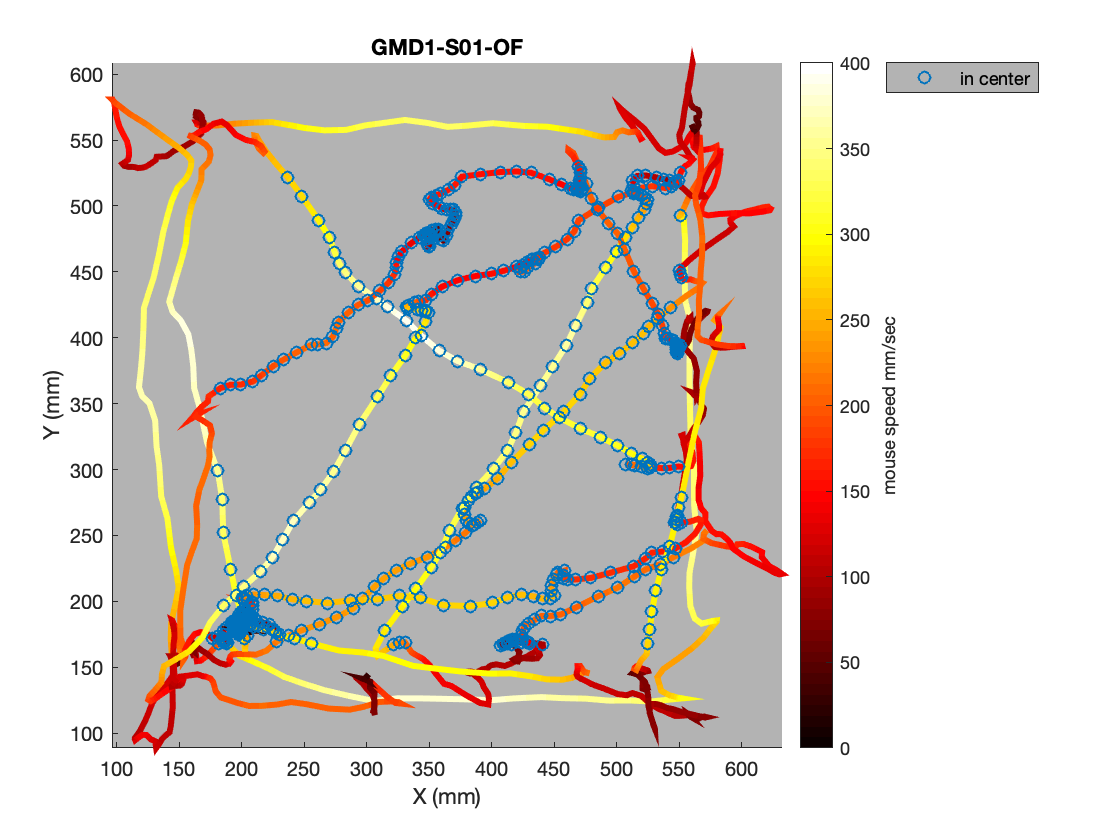

title ( [EXPID '-' SAMPLEID '-' TASKID] );

Plot velocity:

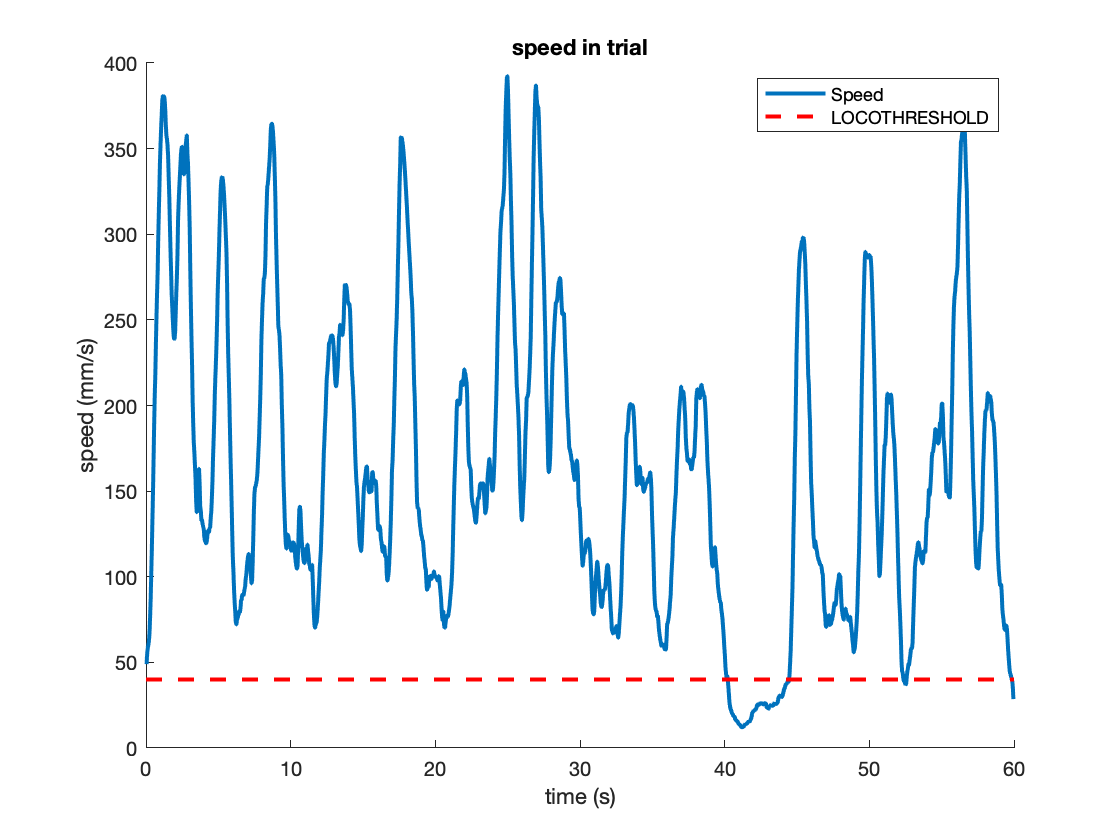

figure; hold on;
xAx = makexAxisFromFrames(nFrames, FRAMERATE);
plot(xAx, speedArray, 'LineWidth', 2);
xlabel('time (s)');
ylabel ('speed (mm/s)');
line([0, max(xAx)], [LOCOTHRESHOLD LOCOTHRESHOLD], 'LineStyle','--', 'LineWidth',2, 'Color', 'r');
legend({'Speed' 'LOCOTHRESHOLD'});
title ('speed in trial');